pX = MATERIAL.CT/B/2/pi/1e3;

fig(1) = figure;
fig1.Position = [488.2,176.2,810.4,484];
clear cr

for ii = 1:incident.n
	tmp = cT{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		cr(ii,imode) = tmp(imode);
	end
end


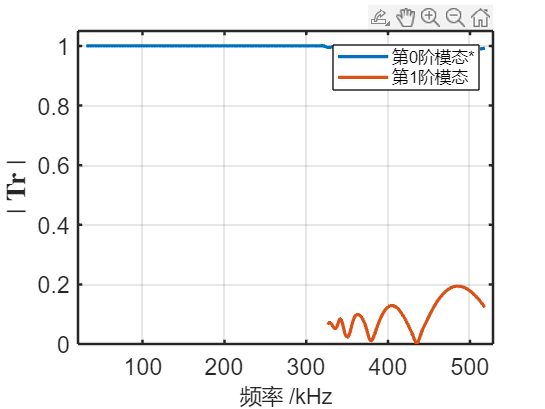

legendText = [];
clear cri pic
for imode = 1:nmode
	idx = find(cr(:,imode));
	iff = incident.w(idx);
	ict = cr(idx,imode);
	ffi = linspace(min(iff),max(iff),250);
	cri(:,imode) = interp1(iff,ict,ffi,'spline');

	ffi = ffi*pX;
	iff = iff*pX;

	if imode == incident.mode
		pic(imode) = plot(ffi,cri(:,imode),SeriesIndex=imode,LineWidth=2);
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态*'])];
		hold on
% 		plot(iff(1:5:end),ict(1:5:end),'*',SeriesIndex=imode)
	else
		pic(imode) = plot(ffi,cri(:,imode),SeriesIndex=imode,LineWidth=2);
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态'])];
		hold on
	end
end
hold off
grid on
legend(legendText,'Location','northeast','FontSize',10)
xlim([min(incident.w*pX)-10,max(incident.w*pX)+10])

xlabel("频率 /kHz")
ylabel("$$\mid\textbf{Tr}\mid$$",Interpreter='latex',FontWeight='bold')
ylim([0 1.05])

ax1 = gca;
ax1.XAxis.LineWidth = 1.5;
ax1.YAxis.LineWidth = 1.5;
ax1.XAxis.FontSize = 14;
ax1.YAxis.FontSize = 14;
ax1.XLabel.FontSize = 13;
ax1.YLabel.FontSize = 16;